# Putain de BAR à la con

## Adhérence

%% paramètre
% Vehicule
g=9.81;
mvec=220; %masse véhicule
mpilote=70;
mt=mvec+mpilote;
rep=0.55; % répartission masse av/ar
%Pneumatique
coeff_adh = 1.55;


## Modèle grossier

A=[1:0.05:1.8];

A =     1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000


Fcoulomb=coeff_adh*mt*g.*ones(1,length(A));

Fcoulomb = 	1.0e+03 *

    4.4096    4.4096    4.4096    4.4096    4.4096    4.4096    4.4096    4.4096    4.4096    4.4096    4.4096    4.4096    4.4096    4.4096    4.4096    4.4096    4.4096


Fdemande=mt.*A*g;

Fdemande = 	1.0e+03 *

    2.8449    2.9871    3.1294    3.2716    3.4139    3.5561    3.6984    3.8406    3.9829    4.1251    4.2674    4.4096    4.5518    4.6941    4.8363    4.9786    5.1208


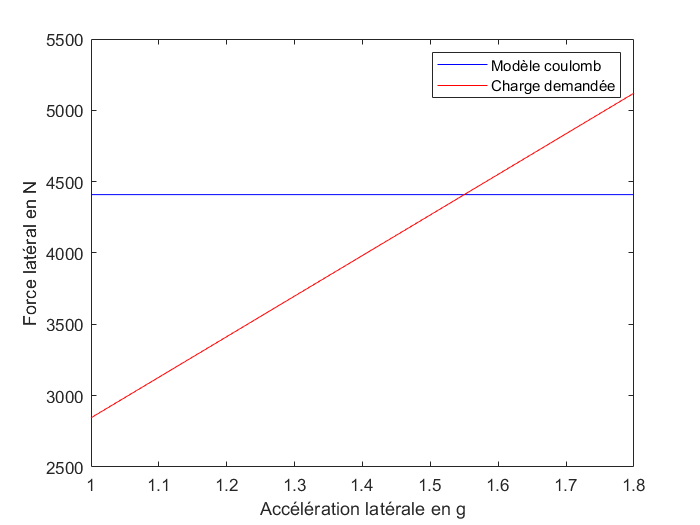


plot(A,Fcoulomb,'b',A,Fdemande,'r')
xlabel('Accélération latérale en g')
ylabel('Force latéral en N')
legend('Modèle coulomb','Charge demandée')

## Modele AV/AR

Fav=mt*(1-rep).*A*g;
Far=mt*rep.*A*g;
Favcoulomb=coeff_adh*mt*(1-rep)*g.*ones(1,length(A));

Favcoulomb = 	1.0e+03 *

    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843    1.9843


Farcoulomb=coeff_adh*mt*rep*g.*ones(1,length(A));

Farcoulomb = 	1.0e+03 *

    2.4253    2.4253    2.4253    2.4253    2.4253    2.4253    2.4253    2.4253    2.4253    2.4253    2.4253    2.4253    2.4253    2.4253    2.4253    2.4253    2.4253


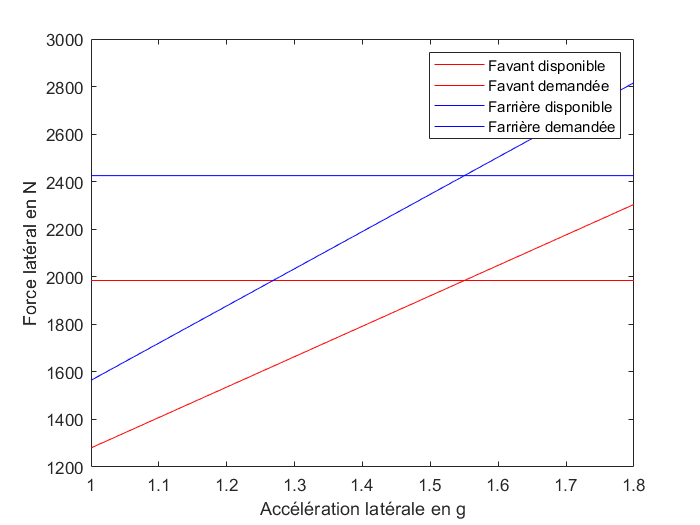


plot(A,Fav,'r',A,Favcoulomb,'r',A,Far,'b',A,Farcoulomb,'b')
xlabel('Accélération latérale en g')
ylabel('Force latéral en N')
legend('Favant disponible','Favant demandée','Farrière disponible','Farrière demandée')

L'arrière décroche en première => sur-vireur

## Modele Raideur anti-roulis


$$F_{\phi}=$$
